单个水体、单个深度的颜色确定流程：

% kd_3 = [0.288 0.122 0.122];
% % RlGlBl_D65 = [0.8413, 4.7424, 0.0655];
% RlGlBl_D65 = [0.9504, 1, 1.0889];
% z = 10;
% beta = z * kd_3
% reduce = exp(-beta)
% RGB_withZ = RlGlBl_D65 .* reduce % ./ RlGlBl_D65
% 
% M_normalize_RGB2XYZ = [0.49 0.31 0.2; 0.17697 0.81240 0.01063; 0 0.01 0.99];
% XYZ_normalize_withZ = M_normalize_RGB2XYZ * RGB_withZ'
% 
% M_XYZ2sRGBn = [3.2404542, -1.5371385, -0.4985314; -0.9692660, 1.8760108, 0.0415560; 0.0556434, -0.2040259, 1.0572252];
% sRGB_normalize_withZ = M_XYZ2sRGBn * XYZ_normalize_withZ
% 
% for i = 1:3
%     if sRGB_normalize_withZ(i,1) > 1
%         sRGB_normalize_withZ(i,1) = 1
%     elseif sRGB_normalize_withZ(i,1) < 0
%         sRGB_normalize_withZ(i,1) = 0
%     elseif sRGB_normalize_withZ(i,1) <= 0.0031308
%         sRGB_normalize_withZ(i,1) = 12.92 *  sRGB_normalize_withZ(i,1)
%     else 
%         sRGB_normalize_withZ(i,1) = 1.055 * power(sRGB_normalize_withZ(i,1), 1 / 2.4) - 0.055;
%     end
% end
% 
% 
% colormapY = [0:1:1]
% colormapX = [0:1:1]
% mymap = sRGB_normalize_withZ'
% pcolor(colormapX, colormapY, [1,2;2,2])
% colormap(mymap)

以下是一个颜色的取色过程（已经预见到累死的结果了）

colors_I  = [213,242,248; 188,227,238; 161,216,234; 139,205,227; 127,196,222; 114,188,219; 104,179,213; 94,171,208; 88,164,201; 82,157,202; 74,149,194; 70,146,191; 65,138,184; 61,132,179; 56,127,177; 53,122,173; 48,117,168; 47,111,163; 44,108,160; 43,104,157] ./ 255;
colors_IA = [211,240,248; 183,224,235; 159,209,231; 139,199,224; 121,189,216; 110,180,211; 98,169,202;  90,162,199; 82,154,192; 76,148,186; 69,137,181; 64,131,174; 60,127,169; 58,121,163; 50,115,160; 47,109,154; 45,103,150; 43,99,147;  38,95,140;  36,91,137] ./ 255;
colors_IB = [214,236,244; 180,221,233; 155,206,225; 133,193,217; 117,183,210; 105,172,201; 93,162,192;  86,154,187; 76,145,178; 69,138,173; 63,128,167; 58,121,160; 54,115,155; 50,110,151; 46,103,145; 44,102,141; 40,94,132;  38,90,128;  37,86,125;  33,79,119] ./ 255;
colors_II = [204,231,237; 170,209,222; 140,191,208; 119,174,195; 102,158,182; 87,146,171;  76,133,162;  67,121,151; 57,111,138; 51,104,131; 44,94,122;  42,88,115;  40,80,109;  35,73,103;  32,69,95;   29,63,87;   24,57,80;   20,56,76;   19,50,70;   14,45,70] ./ 255;
colors_III= [197,219,222; 153,188,198; 121,164,176; 94,142,152;  78,122,134;  62,107,118;  54,93,106;   44,84,94;   37,74,86;   32,62,74;   28,57,63;   20,47,55;   19,42,51;   16,39,49;   12,32,39;   11,29,36;   10,24,31;   9,22,30;    7,19,27;    7,16,23] ./ 255;
colors_1C = [196,219,216; 152,186,184; 120,160,157; 97,140,137;  76,120,116;  65,101,99;   53,90,84;    46,78,73;   38,68,60;   33,58,52;   26,50,45;   24,47,40;   18,41,33;   17,37,33;   12,28,29;   14,27,26;   12,21,23;   11,19,21;   7,18,18;    6,16,16] ./ 255;
colors_3C = [186,202,193; 134,162,147; 102,130,113; 74,103,88;   58,83,69;    42,65,52;    34,54,43;    28,45,35;   20,36,25;   17,28,20;   15,23,17;   11,19,12;   9,15,9;     6,12,8;     5,10,8;     4,8,7;      0,6,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_5C = [173,175,163; 115,124,106; 76,87,67;    51,60,46;    37,45,30;    24,32,21;    16,22,16;    10,15,9;    9,11,7;     6,8,2;      4,6,2;      3,5,0;      2,4,2;      2,2,2;      2,2,2;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_7C = [153,149,123; 91,89,60;    56,53,33;    34,32,16;    21,19,9;     14,10,3;     7,7,3;       4,5,0;      4,5,0;      2,2,0;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;
colors_9C = [129,114,78;  68,52,25;    35,26,11;    18,12,4;     9,7,2;       7,3,0;       5,0,0;       3,0,1;      1,1,1;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0;      0,0,0] ./ 255;

colors = [colors_I; colors_IA; colors_IB; colors_II; colors_III; colors_1C; colors_3C; colors_5C; colors_7C; colors_9C];

z_max = 20;
colorY = 1:z_max;
colorX = 0:10;
p = colors

p =     0.8353    0.9490    0.9725
    0.7373    0.8902    0.9333
    0.6314    0.8471    0.9176
    0.5451    0.8039    0.8902
    0.4980    0.7686    0.8706
    0.4471    0.7373    0.8588
    0.4078    0.7020    0.8353
    0.3686    0.6706    0.8157
    0.3451    0.6431    0.7882
    0.3216    0.6157    0.7922


% C_unit = (1:z_max)';
% C = repmat(C_unit, 1, 11)
colorIndex = [0*z_max+1:1*z_max; 1*z_max+1:2*z_max; 2*z_max+1:3*z_max; 3*z_max+1:4*z_max; 4*z_max+1:5*z_max; 5*z_max+1:6*z_max; 6*z_max+1:7*z_max; 7*z_max+1:8*z_max; 8*z_max+1:9*z_max; 9*z_max+1:10*z_max; 9*z_max+1:10*z_max]'

colorIndex =      1    21    41    61    81   101   121   141   161   181   181
     2    22    42    62    82   102   122   142   162   182   182
     3    23    43    63    83   103   123   143   163   183   183
     4    24    44    64    84   104   124   144   164   184   184
     5    25    45    65    85   105   125   145   165   185   185
     6    26    46    66    86   106   126   146   166   186   186
     7    27    47    67    87   107   127   147   167   187   187
     8    28    48    68    88   108   128   148   168   188   188
     9    29    49    69    89   109   129   149   169   189   189
    10    30    50    70    90   110   130   150   170   190   190


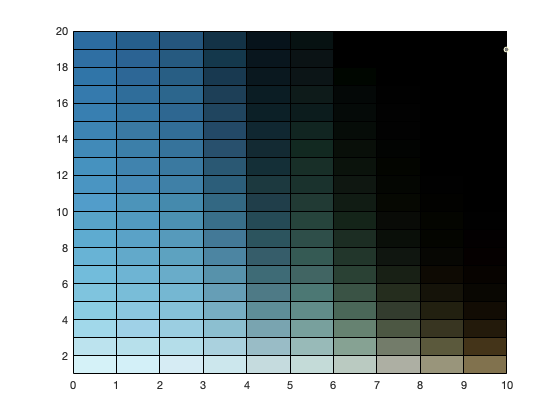


pcolor(colorX, colorY, colorIndex)
colormap(p)